# Eksamen F22 Morten Erichsen

Opgave 1a

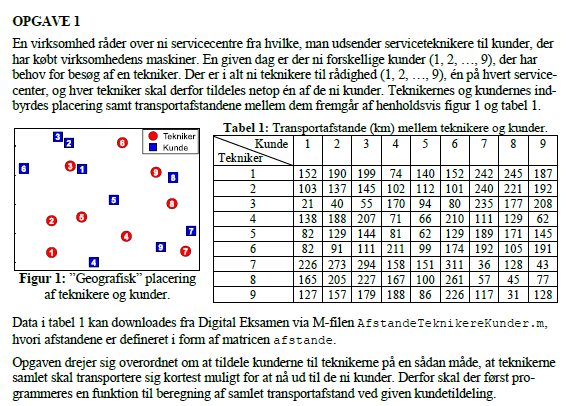

afstande = [152 190 199  74 140 152 242 245 187
            103 137 145 102 112 101 240 221 192
             21  40  55 170  94  80 235 177 208
            138 188 207  71  66 210 111 129  62
             82 129 144  81  62 129 189 171 145
             82  91 111 211  99 174 192 105 191
            226 273 294 158 151 311  36 128  43
            165 205 227 167 100 261  57  45  77
            127 157 179 188  86 226 117  31 128];


% Tekniker 1 får kunde 8, osv..
kundetildelt = [8 3 6 1 7 9 4 2 5];

afst = [];

for i = 1:length(kundetildelt)

    % der skal indekseres korrekt, for at summen af afstandende passer
    afst(end + 1) = afstande(i, kundetildelt(i));
        
end

sum(afst)

ans = 1437


samletafst(kundetildelt,afstande)

ans = 1437

Opgave 1b

AfstandeTeknikereKunder;        % Definér afstandsmatricen afstande
n = length(afstande);
tildelingsmuligh = perms(1:n);  % Generér alle tildelingsmuligheder
N = factorial(n);               % Antal tildelingsmuligheder = n!
minsamletafstand = +inf;        % Initialværdi
for i = 1:N
  kundetildelt = tildelingsmuligh(i,:);
  samletafstand = samletafst(kundetildelt,afstande);
  if samletafstand < minsamletafstand && kundetildelt(1) ~= 4 && kundetildelt(4) == 7
    minsamletafstand = samletafstand;
  end
end
optkundetildelt = kundetildelt                 % Vis indhold af optkundetildelt

optkundetildelt =      1     2     3     4     5     6     7     8     9


minsamletafstand

minsamletafstand = 765

Opgave 2

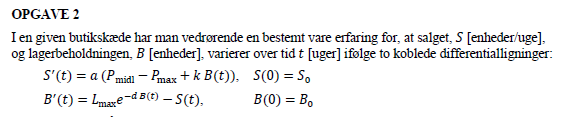

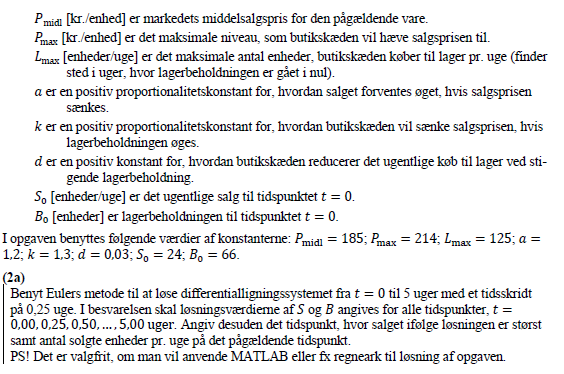D

% Givne værdier
clear

Pmidl=185; Pmax=214; Lmax=125; a=1.2; k=1.3; d=0.03; S0=24; B0=66;

t = [0, 5];
h = 0.25;

dYdt = @(t, Y) [a*(Pmidl - Pmax + k*Y(2)), Lmax*exp(-d*Y(2)) - Y(1)]

dYdt = function_handle with value:
    @(t,Y)[a*(Pmidl-Pmax+k*Y(2)),Lmax*exp(-d*Y(2))-Y(1)]



[t, Y] = eulsys(dYdt,t, [S0, B0],h);

S = Y(:, 1);
B = Y(:, 2);

disp(table(t, S, B, 'VariableNames',{'t, uger', 'S, enheder/uge', 'B, enheder'}))

    t, uger    S, enheder/uge    B, enheder
    _______    ______________    __________

        0              24              66  
     0.25           41.04          64.315  
      0.5          57.423          58.593  
     0.75          71.574          49.626  
        1          82.228          38.784  
     1.25          88.654          27.989  
      1.5          90.869          19.321  
     1.75          89.704          14.107  
        2          86.506          12.148  
     2.25          82.544          12.227  
      2.5          78.612          13.246  
     2.75          75.078          14.595  
        3           72.07          15.995  
     3.25          69.608          17.317  
      3.5          67.662          18.503  
     3.75          66.178          19.526  
        4          65.093          20.377  
     4.25           64.34          21.061  
      4.5        


[maks, s] = max(S)

maks = 90.8693

s = 7


t(s)

ans = 1.5000

B(s)

ans = 19.3209

Det ses at salget er størst efter 1.5 uger, med en værdi på ~91 enheder

Funktionen eulsys er brugt til løsningen

## Opgave 2b

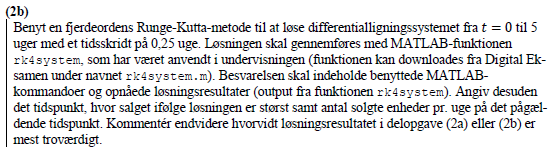

clear

Pmidl=185; Pmax=214; Lmax=125; a=1.2; k=1.3; d=0.03; S0=24; B0=66;

t = [0, 5];
h = 0.25;

dYdt = @(t, Y) [a*(Pmidl - Pmax + k*Y(2)), Lmax*exp(-d*Y(2)) - Y(1)]

dYdt = function_handle with value:
    @(t,Y)[a*(Pmidl-Pmax+k*Y(2)),Lmax*exp(-d*Y(2))-Y(1)]



[t,Y] = rk4system(dYdt,t,[S0, B0],h);

S = Y(:, 1);
B = Y(:, 2);

disp(table(t, S, B, 'VariableNames',{'t, uger', 'S, enheder/uge', 'B, enheder'}))

    t, uger    S, enheder/uge    B, enheder
    _______    ______________    __________

        0              24              66  
     0.25           40.46          62.428  
      0.5          54.885          55.741  
     0.75          66.295          47.196  
        1          74.248          38.261  
     1.25          78.869            30.3  
      1.5          80.728          24.191  
     1.75           80.61          20.151  
        2          79.276          17.883  
     2.25          77.323          16.897  
      2.5           75.16          16.735  
     2.75          73.037          17.054  
        3          71.094          17.626  
     3.25          69.399          18.303  
      3.5          67.972          18.996  
     3.75          66.811          19.653  
        4          65.893          20.244  
     4.25           65.19          20.755  
      4.5        


[maks, s] = max(S)

maks = 80.7276

s = 7


t(s)

ans = 1.5000

B(s)

ans = 24.1915

Det ses at salget er størst efter 1.5 uger, med en værdi på ~81 enheder

Funktionen rk4system er brugt til løsningen

Den her metode må være mere præcis, eftersom den er af 4. orden, hvor eulers er 1. orden

## Opgave 3

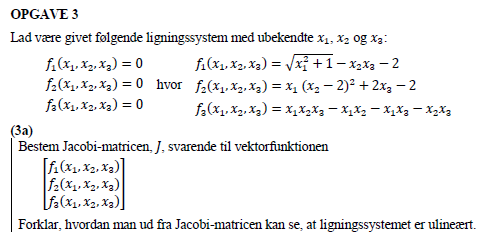

clear

syms x1 x2 x3

f1 = sqrt(x1^2 + 1) - x2*x3 - 2

$$f1 = \sqrt{{x_{1}}^{2}+1}-x_{2}\,x_{3}-2$$

f2 = x1*(x2 - 2)^2 + 2*x3 - 2

$$f2 = 2\,x_{3}+x_{1}\,{\left(x_{2}-2\right)}^{2}-2$$

f3 = x1*x2*x3 - x1*x2 - x1*x3 - x2*x3

$$f3 = x_{1}\,x_{2}\,x_{3}-x_{1}\,x_{3}-x_{2}\,x_{3}-x_{1}\,x_{2}$$


fs = [f1;f2;f3]

$$fs = \left(\begin{array}{c} \sqrt{{x_{1}}^{2}+1}-x_{2}\,x_{3}-2\\ 2\,x_{3}+x_{1}\,{\left(x_{2}-2\right)}^{2}-2\\ x_{1}\,x_{2}\,x_{3}-x_{1}\,x_{3}-x_{2}\,x_{3}-x_{1}\,x_{2} \end{array}\right)$$

vars = [x1,x2,x3];

J = jacobian(fs, vars)

$$J = \left(\begin{array}{ccc} \frac{x_{1}}{\sqrt{{x_{1}}^{2}+1}} & -x_{3} & -x_{2}\\ {\left(x_{2}-2\right)}^{2} & x_{1}\,\left(2\,x_{2}-4\right) & 2\\ x_{2}\,x_{3}-x_{3}-x_{2} & x_{1}\,x_{3}-x_{3}-x_{1} & x_{1}\,x_{2}-x_{2}-x_{1} \end{array}\right)$$


% Jacobi-matricen består af de ukendte er den ulineær


Det vil ikke du, eftersom række 2 i jacobian matricen ville give:

expand((x2-2)^2) == 2

$$ans = {x_{2}}^{2}-4\,x_{2}+4=2$$

disp('4 + 0 + 2 = 0')

4 + 0 + 2 = 0



Jny = subs(J, [x1,x2,x3], [0,0,0])

$$Jny = \left(\begin{array}{ccc} 0 & 0 & 0\\ 4 & 0 & 2\\ 0 & 0 & 0 \end{array}\right)$$


inv(Jny)

$$ans = \left(\begin{array}{ccc} \infty & 0 & 0\\ 0 & \infty & 0\\ 0 & 0 & \infty \end{array}\right)$$

Hvilket ikke giver mening.

Ydermere kan den ikke inverteres, som er nødvendig i newtraph metoden

x = [-2; 3; 2]

x =     -2
     3
     2



for i = 1:6

    f = [sqrt(x(1)^2+1) - x(2)*x(3) - 2
        x(1)*(x(2)-2)^2 + 2*x(3) - 2
        x(1)*x(2)*x(3) - x(1)*x(2) - x(1)*x(3) - x(2)*x(3)];

    J = [x(1)/sqrt(x(1)^2+1) -x(3) -x(2)
        (x(2)-2)^2 2*x(1)*(x(2)-2) 2
        x(2)*x(3)-x(2)-x(3) x(1)*x(3)-x(1)-x(3) x(1)*x(2)-x(1)-x(2)];

    x = x - J\f

end

x =    -3.5837
    2.1596
    1.1111


x =    -5.4285
    2.6661
    1.3589


x =    -5.0210
    2.4373
    1.2865


x =    -4.9242
    2.3529
    1.2856


x =    -4.9159
    2.3424
    1.2878


x =    -4.9158
    2.3422
    1.2879


# Opgave 4

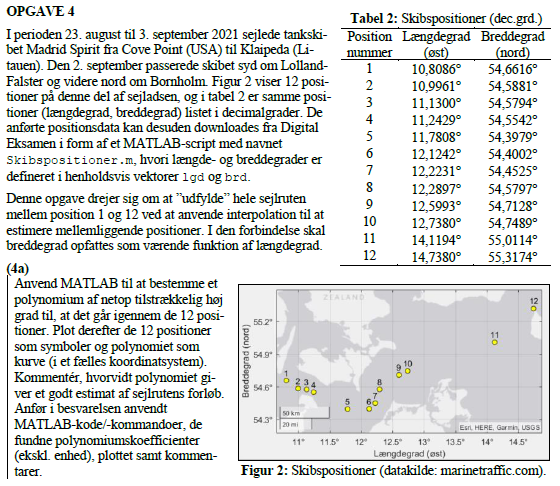

clear

lgd = [10.8086 10.9961 11.1300 11.2429 11.7808 12.1242 12.2231 12.2897 12.5993 12.7380 14.1194 14.7380]; % Længdegrad øst (decimalgrader) 
brd = [54.6616 54.5881 54.5794 54.5541 54.3979 54.4002 54.4525 54.5797 54.7128 54.7489 55.0114 55.3174]; % Breddegrad nord (decimalgrader)

format short

n = length(lgd)

n = 12


koeff = polyfit(lgd, brd, n-1)';



T = table(koeff, lgd', brd', 'VariableNames',{'Koeff', 'Længdegrader', 'Breddegrader'});
disp(T)

       Koeff       Længdegrader    Breddegrader
    ___________    ____________    ____________

        -18.459       10.809          54.662   
           2499       10.996          54.588   
    -1.5363e+05        11.13          54.579   
     5.6619e+06       11.243          54.554   
    -1.3898e+08       11.781          54.398   
     2.3858e+09       12.124            54.4   
    -2.9229e+10       12.223          54.453   
     2.5556e+11        12.29           54.58   
    -1.5627e+12       12.599          54.713   
     6.3649e+12       12.738          54.749   
    -1.5542e+13       14.119          55.011   
     1.7235e+13       14.738          55.317   



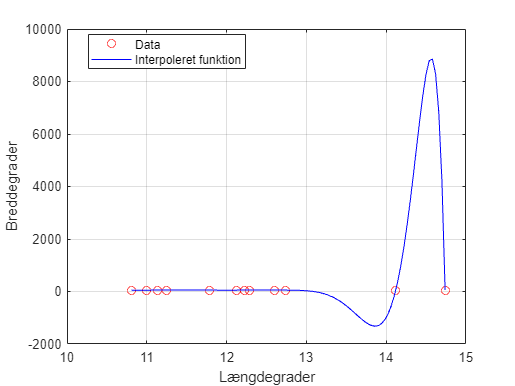


% der plottes for at se hvor godt fittet er

lgdlin = linspace(min(lgd), max(lgd));
brds = polyval(koeff, lgdlin);

plot(lgd, brd, 'ro', 'DisplayName', 'Data'), grid("on")
xlabel('Længdegrader'), ylabel('Breddegrader')
hold on
plot(lgdlin, brds,'b', 'DisplayName','Interpoleret funktion')

xlabel('Længdegrader'), ylabel('Breddegrader')
legend('Location','best')
hold off

Plottet giver ikke en god ide om sejlrutens forløb, eftersom vi har med et 12. grads polynomie at gøre. Det rammer alle punkter, men den høje grad gør den meget upræcis

## Opgave b

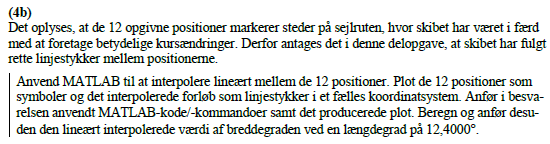


lgd1 = linspace(min(lgd), max(lgd))

lgd1 =    10.8086   10.8483   10.8880   10.9277   10.9674   11.0071   11.0467   11.0864   11.1261   11.1658   11.2055   11.2452   11.2849   11.3246   11.3643   11.4040   11.4437   11.4833   11.5230   11.5627   11.6024   11.6421   11.6818   11.7215   11.7612   11.8009   11.8406   11.8803   11.9199   11.9596   11.9993   12.0390   12.0787   12.1184   12.1581   12.1978   12.2375   12.2772   12.3169   12.3565   12.3962   12.4359   12.4756   12.5153   12.5550   12.5947   12.6344   12.6741   12.7138   12.7535


brd1 = interp1(lgd, brd, lgd1, 'linear') 

brd1 =    54.6616   54.6460   54.6305   54.6149   54.5994   54.5874   54.5848   54.5822   54.5797   54.5714   54.5625   54.5534   54.5419   54.5304   54.5189   54.5073   54.4958   54.4843   54.4728   54.4612   54.4497   54.4382   54.4266   54.4151   54.4036   54.3980   54.3983   54.3986   54.3988   54.3991   54.3994   54.3996   54.3999   54.4002   54.4181   54.4391   54.4800   54.5558   54.5914   54.6084   54.6255   54.6426   54.6596   54.6767   54.6938   54.7108   54.7219   54.7323   54.7426   54.7518


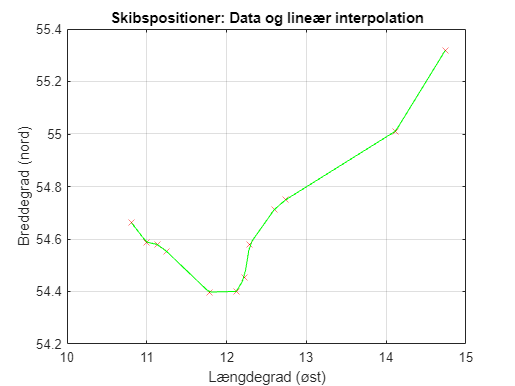


plot(lgd,brd,"rx", lgd1, brd1,'g')
title('Skibspositioner: Data og lineær interpolation')
xlabel('Længdegrad (øst)')
ylabel('Breddegrad (nord)')
grid

breddegrad_ved_12_4_ost = interp1(lgd,brd,12.4,'Linear')

breddegrad_ved_12_4_ost = 54.6271

## Opgave c

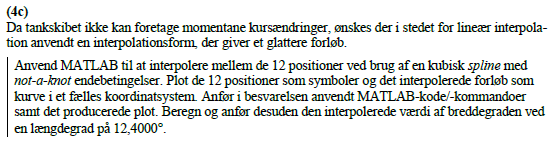

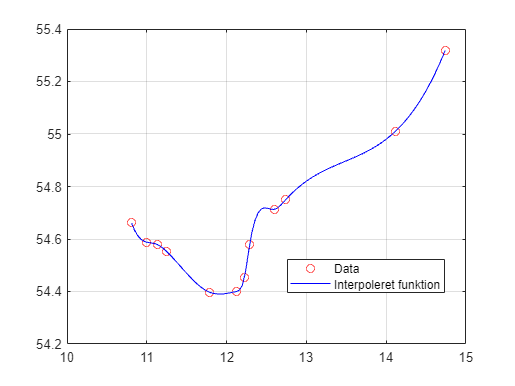

spl_func = spline(lgd,brd,lgdlin);

plot(lgd,brd, 'ro', 'DisplayName', 'Data'), grid("on")
hold on
plot(lgdlin, spl_func,'b', 'DisplayName','Interpoleret funktion')

legend('Location','best')
hold off


breddegrad_ved_12_4_ost = spline(lgd,brd,12.4)

breddegrad_ved_12_4_ost = 54.7020

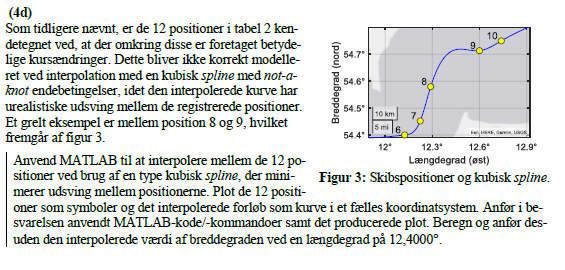

lgd1 = linspace(min(lgd), max(lgd))

lgd1 =    10.8086   10.8483   10.8880   10.9277   10.9674   11.0071   11.0467   11.0864   11.1261   11.1658   11.2055   11.2452   11.2849   11.3246   11.3643   11.4040   11.4437   11.4833   11.5230   11.5627   11.6024   11.6421   11.6818   11.7215   11.7612   11.8009   11.8406   11.8803   11.9199   11.9596   11.9993   12.0390   12.0787   12.1184   12.1581   12.1978   12.2375   12.2772   12.3169   12.3565   12.3962   12.4359   12.4756   12.5153   12.5550   12.5947   12.6344   12.6741   12.7138   12.7535


brd1 = interp1(lgd, brd, lgd1, 'PCHIP') 

brd1 =    54.6616   54.6394   54.6199   54.6040   54.5928   54.5870   54.5844   54.5826   54.5798   54.5736   54.5639   54.5535   54.5426   54.5299   54.5159   54.5010   54.4857   54.4703   54.4553   54.4412   54.4283   54.4172   54.4082   54.4017   54.3983   54.3979   54.3979   54.3980   54.3982   54.3984   54.3987   54.3991   54.3995   54.4001   54.4081   54.4320   54.4733   54.5628   54.6003   54.6255   54.6458   54.6624   54.6761   54.6882   54.6996   54.7114   54.7232   54.7337   54.7433   54.7524


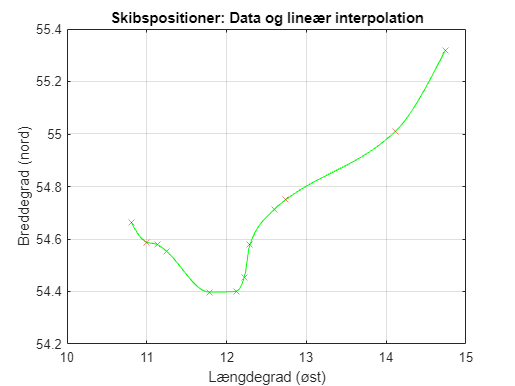


plot(lgd,brd,"rx", lgd1, brd1,'g')
title('Skibspositioner: Data og lineær interpolation')
xlabel('Længdegrad (øst)')
ylabel('Breddegrad (nord)')
grid

breddegrad_ved_12_4_ost = interp1(lgd,brd,12.4,'PCHIP')

breddegrad_ved_12_4_ost = 54.6475

# Opgave 5

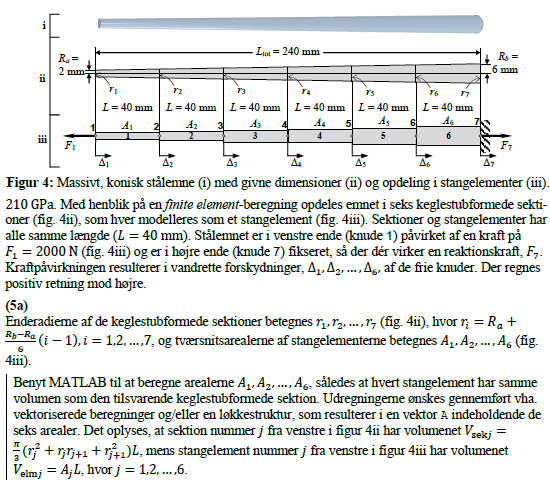

clear
L_tot = 240;
opdel = 6;
L = L_tot/opdel;

Ra = 2;
Rb = 6;

F1 = 2000;

% A = pi * r
r_kon = [];

for i = 1:opdel+1
    r_kon(end +1) = Ra + (Rb-Ra)/6 * (i-1);
end

r_kon;
V_kon = [];

for j = 1:opdel
    V_kon(end +1) = pi/3 * (r_kon(j)^2 + r_kon(j)*r_kon(j+1) + r_kon(j+1)^2)/L;
    
    Arealer = V_kon*L;
end

Arealer

Arealer =    17.2206   28.3907   42.3533   59.1085   78.6562  100.9964


## Opgave b

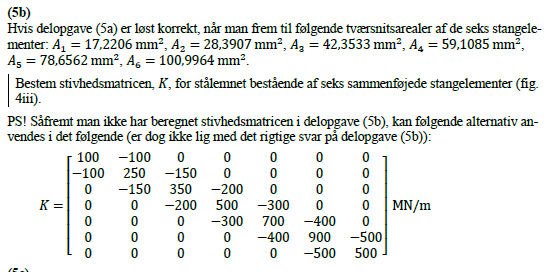

As = Arealer

As =    17.2206   28.3907   42.3533   59.1085   78.6562  100.9964


Ls = [40,40,40,40,40,40]

Ls =     40    40    40    40    40    40


Es = [210,210,210,210,210,210]

Es =    210   210   210   210   210   210


 
n = opdel;

K = zeros(n+1, n+1);
for j = 1:n
    k= As(j)*Es(j)/Ls(j);

    Kelm = [k, -k; -k, k];

    K(j:j+1,j:j+1) = K(j:j+1,j:j+1) + Kelm;

end

K

K =    90.4081  -90.4081         0         0         0         0         0
  -90.4081  239.4592 -149.0511         0         0         0         0
         0 -149.0511  371.4061 -222.3549         0         0         0
         0         0 -222.3549  532.6745 -310.3195         0         0
         0         0         0 -310.3195  723.2644 -412.9449         0
         0         0         0         0 -412.9449  943.1759 -530.2310
         0         0         0         0         0 -530.2310  530.2310


Pfri = [-F1 0 0 0 0 0]';    % Eksterne kræfter på de frie knuder (N)
Kfri = K(1:6,1:6);          % Del af stivhedsmatrix svarende til frie knuder (N/m)
D = Kfri\Pfri;              % Forskydninger af de frie knuder (m)
D_my = D'              % Forskydninger omregnet til/vist i mikrometer

D_my =   -59.5949  -37.4730  -24.0548  -15.0602   -8.6152   -3.7719


# Funktioner

function sa = samletafst(kundetildelt,afstande)

afst = [];

for i = 1:length(kundetildelt)

    % der skal indekseres korrekt, for at summen af afstandende passer
    afst(end + 1) = afstande(i, kundetildelt(i));
        
end

sa = sum(afst);


end

%%

function [t,y,iter] = eulode(dydt,tspan,y0,h)
% eulode: Euler ODE solver
%   [t,y] = eulode(dydt,tspan,y0,h):
%           uses Euler's method to integrate an ODE
% input:
%   dydt = name of the M-file that evaluates the ODE
%   tspan = [ti, tf] where ti and tf = initial and
%   final values of independent variable
%   y0 = initial value of dependent variable
%   h = step size
% output:
%   t = vector of independent variable
%   y = vector of solution for dependent variable
if nargin<4,error('at least 4 input arguments required'),end
ti = tspan(1);tf = tspan(2);
if ~(tf>ti),error('upper limit must be greater than lower'),end
t = (ti:h:tf)'; n = length(t);
% if necessary, add an additional value of t
% so that range goes from t = ti to tf
if t(n)<tf
    t(n+1) = tf;
    n = n+1;
end
y = y0*ones(n,1); %preallocate y to improve efficiency
iter = [0,];
for i = 1:n-1 %implement Euler's method
    iter(end+1) = i;
    y(i+1) = y(i) + dydt(t(i),y(i))*(t(i+1)-t(i));
end
iter = iter';
end


function [t,Y] = eulsys(dYdt,tspan,Y0,h)
% eulsys: Euler solver for a system of ODEs
%   [t,Y] = eulsys(dYdt,tspan,Y0,h): uses Euler's
%     method to solve a system of first order 
%     differential equations.
% input:
%   dYdt = a function of (t,Y), where t is the independent
%     variable (scalar) and Y is a row vector of the 
%     dependent variables. The function should return a
%     row vector of derivatives of the independent
%     variables as given by the differential equations.
%   tspan = [ti, tf] where ti and tf = initial and
%     final values of independent variable
%   Y0 = initial value of dependent variables (row
%     vector)
%   h = step size
% output:
%   t = vector with values of the independent variable
%   Y = matrix with solution values of the dependent
%     variables. Each column represents one dependent 
%     variable
ti = tspan(1);
tf = tspan(2);
t = (ti:h:tf)';
n = length(t);
Y(1,:) = Y0;
for i = 1:n-1
  Y(i+1,:) = Y(i,:) + dYdt(t(i),Y(i,:))*h;
end
end


function [t,Y] = rk4system(dYdt,tspan,Y0,h)
% rk4system: Fourth order Runge-Kutta solver for a system
%            of ODEs
%   [t,Y] = rk4system(dYdt,tspan,Y0,h): uses a fourth 
%     order Runge-Kutta method to solve a system of
%     first order differential equations.
% input:
%   dYdt = a function of (t,Y), where t is the independent
%     variable (scalar) and Y is a row vector of the 
%     dependent variables. The function should return a
%     row vector of derivatives of the independent
%     variables as given by the differential equations.
%   tspan = [ti, tf] where ti and tf = initial and
%     final values of independent variable
%   Y0 = initial value of dependent variables (row
%     vector)
%   h = step size
% output:
%   t = vector with values of the independent variable
%   Y = matrix with solution values of the dependent
%     variables. Each column represents one dependent 
%     variable
ti = tspan(1);
tf = tspan(2);
t = (ti:h:tf)';
n = length(t);
Y(1,:) = Y0;
for i = 1:n-1
  k1 = dYdt(t(i),Y(i,:));
  tmid1 = t(i) + h/2;
  Ymid1 = Y(i,:) + k1*h/2;
  k2 = dYdt(tmid1,Ymid1);
  tmid2 = t(i) + h/2;
  Ymid2 = Y(i,:) + k2*h/2;
  k3 = dYdt(tmid2,Ymid2);
  tend = t(i) + h;
  Yend = Y(i,:) + k3*h;
  k4 = dYdt(tend,Yend);
  phi = (k1 + 2*k2 + 2*k3 + k4)/6;
  Y(i+1,:) = Y(i,:) + phi*h;
end
end


function [root,ea,iter]=newtraph(func,dfunc,xr,es,maxit)
% newtraph: Newton-Raphson root location zeroes
%   [root,ea,iter]=newtraph(func,dfunc,xr,es,maxit):
%         uses Newton-Raphson method to find the root of func
% input:
%   func = name of function
%   dfunc = name of derivative of function
%   xr = initial guess
%   es = desired relative error (default = 0.0001%)
%   maxit = maximum allowable iterations (default = 50)
% output:
%   root = real root
%   ea = approximate relative error (%)
%   iter = number of iterations

if nargin<3,error('at least 3 input arguments required'),end
if nargin<4||isempty(es),es=0.0001; end
if nargin<5||isempty(maxit),maxit=50; end
iter = 0;
while 1
    xrold = xr;
    xr = xr - func(xr)/dfunc(xr);
    iter = iter + 1;
    if xr ~= 0, ea = abs((xr - xrold)/xr) * 100; end
    if ea <= es || iter >= maxit, break, end
end
root = xr;
end

function K = barstiffmat(L, A, E)
    k = E.*A./L;

    [K] = [k, -k; -k, k];

end
